# Waste Analysis Demo

Use the `ThermoeconomicModel` function to perform a waste analysis

### **Create the Thermoeconomic Model**

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
model=ThermoeconomicModel(file,'DiagnosisMethod','NONE','Debug',false);

### Show the results for the reference state

Show the direct unit cost table values

showResults(model,'ducost');

Process Unit Exergy Cost

Key      kP*(J/J)   kPe*(J/J)   kPr*(J/J)    kF*(J/J)    kR*(J/J)      k(J/J)
——————————————————————————————————————————————————————————————————————————————
BLR        1.5514      1.3486      0.2027      1.0000      0.2027      1.3486
TRB        2.0000      1.7244      0.2756      1.5918      0.0068      1.2521
IHE        2.3905      1.8832      0.5072      1.5918      0.2137      1.3675
PMP        2.4366      2.0161      0.4206      2.0000      0.0984      1.1691
CND        1.5918      1.3772      0.2146      1.5918      0.0000      1.0000



### Define Waste Analysis Parameters

Perform a waste analysis for State noIHE (without IHE), recycling 40% of heat in the conderser,

model.State='noIHE';
WasteFlows=convertCharsToStrings(model.WasteFlows);
model.ActiveWaste=convertStringsToChars(WasteFlows(1));
model.setWasteType('HYBRID');
model.setWasteRecycled(0.4);

#### Show Waste Allocation Graph

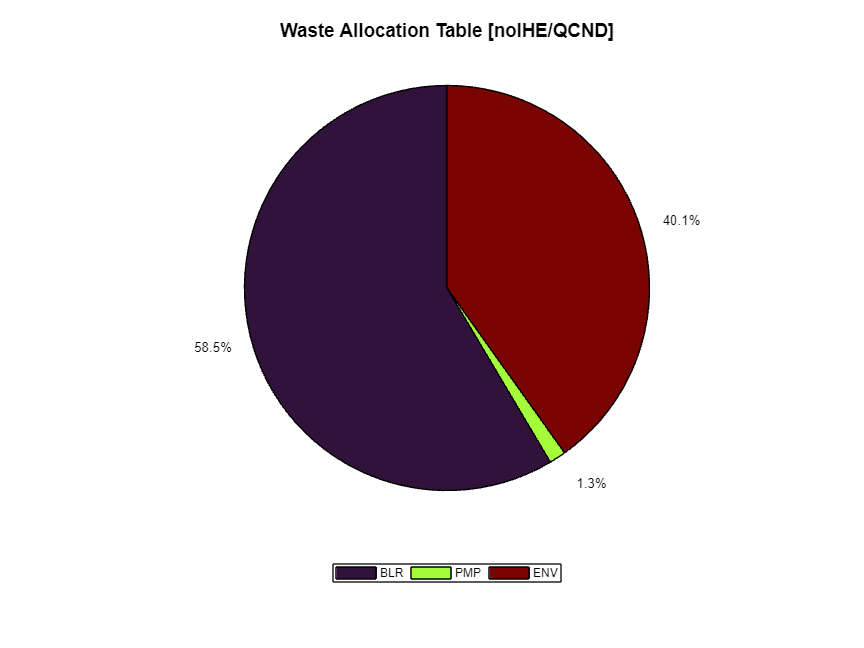

ShowGraph(model,'Graph',cType.Tables.WASTE_ALLOCATION);

####  Show cost values and graphs for the study case (noIHE)

showResults(model,'ducost')

Process Unit Exergy Cost

Key      kP*(J/J)   kPe*(J/J)   kPr*(J/J)    kF*(J/J)    kR*(J/J)      k(J/J)
——————————————————————————————————————————————————————————————————————————————
BLR        1.5602      1.4123      0.1479      1.0000      0.1479      1.4123
TRB        1.9845      1.7913      0.1931      1.5839      0.0013      1.2521
IHE        0.0000      0.0000      0.0000      0.0000      0.0000      1.0000
PMP        2.4418      2.0943      0.3475      1.9845      0.1217      1.1691
CND        1.5839      1.4306      0.1532      1.5839      0.0000      1.0000



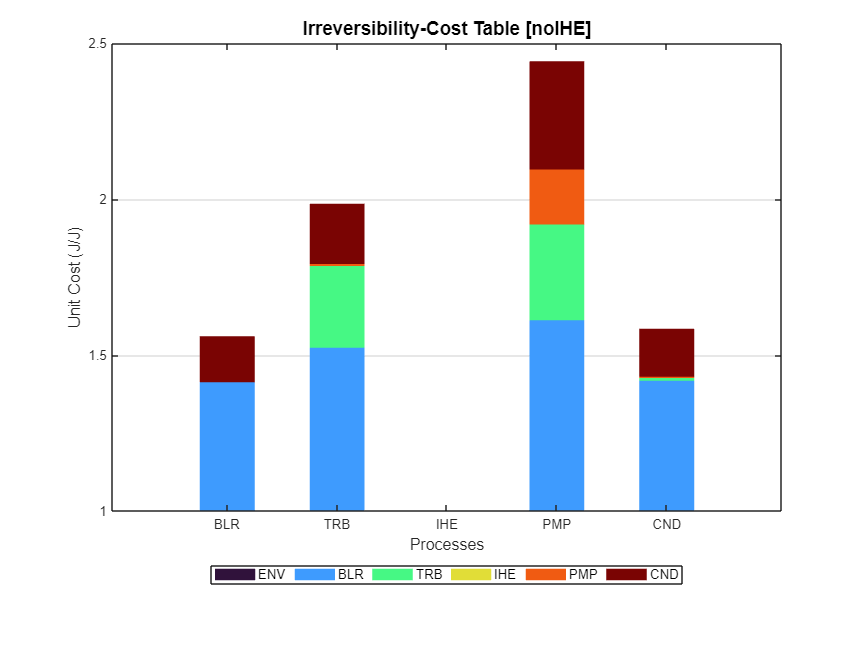

showGraph(model,cType.Tables.PROCESS_ICT);

### Recycling Analysis

Show the recycling analysis graph

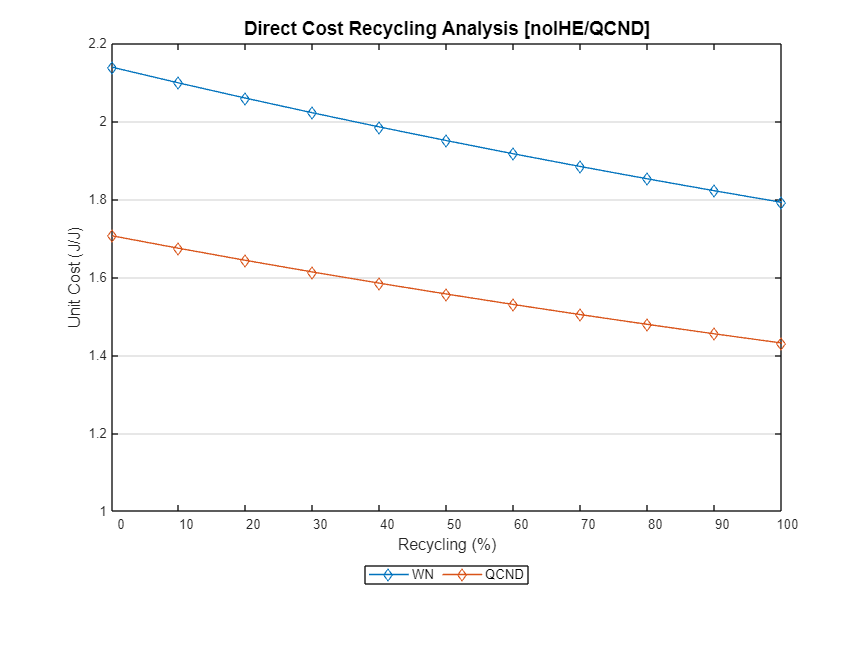

model.Recycling=true;
showGraph(model,cType.Tables.WASTE_RECYCLING_DIRECT);